# HW 5

syms x theta xdot thetadot K m g M l u

z = [x; theta; xdot; thetadot;]

$$z = \left(\begin{array}{c} x\\ \theta \\ \mathrm{xdot}\\ \mathrm{thetadot} \end{array}\right)$$

zdot = [xdot; thetadot; ((-m*g)*theta/M)+(u/M); (((M+m)*g)*theta/(M*l))-(u/(M*l))]

$$zdot = \left(\begin{array}{c} \mathrm{xdot}\\ \mathrm{thetadot}\\ \frac{u}{M}-\frac{g\,m\,\theta }{M}\\ \frac{g\,\theta \,\left(M+m\right)}{M\,l}-\frac{u}{M\,l} \end{array}\right)$$


A = jacobian(zdot, z)

$$A = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & -\frac{g\,m}{M} & 0 & 0\\ 0 & \frac{g\,\left(M+m\right)}{M\,l} & 0 & 0 \end{array}\right)$$

B = jacobian(zdot, u)

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{M}\\ -\frac{1}{M\,l} \end{array}\right)$$

eigen_values = eig(A)

$$eigen\_values = \left(\begin{array}{c} 0\\ 0\\ -\sqrt{\frac{g\,\left(M+m\right)}{M\,l}}\\ \sqrt{\frac{g\,\left(M+m\right)}{M\,l}} \end{array}\right)$$


C = [B  A*B A^2*B   A^3*B]

$$C = \left(\begin{array}{cccc} 0 & \frac{1}{M} & 0 & \frac{g\,m}{M^{2}\,l}\\ 0 & -\frac{1}{M\,l} & 0 & -\frac{g\,\left(M+m\right)}{M^{2}\,l^{2}}\\ \frac{1}{M} & 0 & \frac{g\,m}{M^{2}\,l} & 0\\ -\frac{1}{M\,l} & 0 & -\frac{g\,\left(M+m\right)}{M^{2}\,l^{2}} & 0 \end{array}\right)$$

rank(C)

ans =      4



pole1 = -5;
pole2 = -4;
pole3 = -3+2i;
pole4 = -3-2i;
syms lambda
characteristic_equation = (lambda-pole1)*(lambda-pole2)*(lambda-pole3)*(lambda-pole4)

$$characteristic\_equation = \left(\lambda +4\right)\,\left(\lambda +5\right)\,\left(\lambda +3-2\,\mathrm{i}\right)\,\left(\lambda +3+2\,\mathrm{i}\right)$$

format shortg
sym2poly(characteristic_equation)

ans =      1    15    87   237   260


characteristic_equation = expand(characteristic_equation)

$$characteristic\_equation = \lambda^{4}+15\,\lambda^{3}+87\,\lambda^{2}+237\,\lambda +260$$


K = simplify([0  0   0   1]*inv(C)*( A^4 + 15*A^3 + 87*A^2 + 237*A + 260*eye(4)))

$$K = \left(\begin{array}{cccc} -\frac{260\,M\,l}{g} & -\frac{M\,g^{2}+260\,M\,l^{2}+g^{2}\,m+87\,M\,g\,l}{g} & -\frac{237\,M\,l}{g} & -\frac{3\,M\,l\,\left(5\,g+79\,l\right)}{g} \end{array}\right)$$


Ahat = simplify(A - B*K)

$$Ahat = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ \frac{260\,l}{g} & \frac{g^{2}+87\,g\,l+260\,l^{2}}{g} & \frac{237\,l}{g} & \frac{3\,l\,\sigma_{1}}{g}\\ -\frac{260}{g} & -\frac{87\,g+260\,l}{g} & -\frac{237}{g} & -\frac{3\,\sigma_{1}}{g} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=5\,g+79\,l \end{array}$$


expand(Ahat(4, 4))

$$ans = -\frac{237\,l}{g}-15$$

Ks = [-1; -3; -5;  -8];
Zdots = {};
time = 0:0.1:5;

A_subbed = subs(A, [M m l g], [10 1 1 9.8])

$$A\_subbed = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & -\frac{49}{50} & 0 & 0\\ 0 & \frac{539}{50} & 0 & 0 \end{array}\right)$$

B_subbed = subs(B, [M m l g], [10 1 1 9.8])

$$B\_subbed = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{10}\\ -\frac{1}{10} \end{array}\right)$$

C_subbed = subs(C, [M m l g], [10 1 1 9.8])

$$C\_subbed = \left(\begin{array}{cccc} 0 & \frac{1}{10} & 0 & \frac{49}{500}\\ 0 & -\frac{1}{10} & 0 & -\frac{539}{500}\\ \frac{1}{10} & 0 & \frac{49}{500} & 0\\ -\frac{1}{10} & 0 & -\frac{539}{500} & 0 \end{array}\right)$$

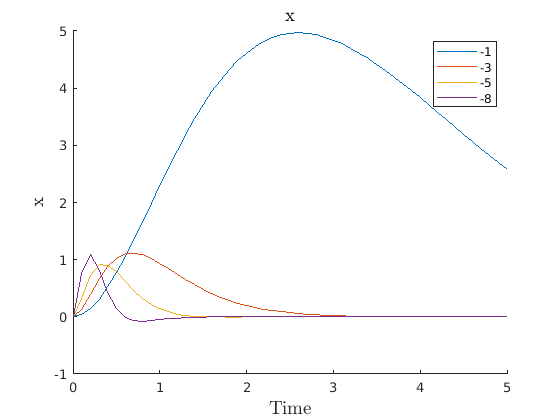


for i = 1:length(Ks)
    characteristic_equation = (lambda-Ks(i))^4;
    coeffs = sym2poly(characteristic_equation);
    K = [0 0 0 1]*inv(C_subbed)*( coeffs(1)*A_subbed^4 + coeffs(2)*A_subbed^3 + coeffs(3)*A_subbed^2 + coeffs(4)*A_subbed + coeffs(5)*eye(4) );
    Ahat = eval(A_subbed-B_subbed*K);
    
    [t, zdots] = ode45(@(t, z) Ahat*z, time, [0; 0.5; 0; 0;]);
    Zdots{end+1} = zdots;
end

figure
hold on;

title("x", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("x", 'Interpreter', 'latex', "FontSize", 14);

for i = 1:length(Ks)
   plot(time, Zdots{i}(:,1)) 
end

legend(string(Ks))

hold off;
exportgraphics(gcf,'x_plot.png','Resolution',300)

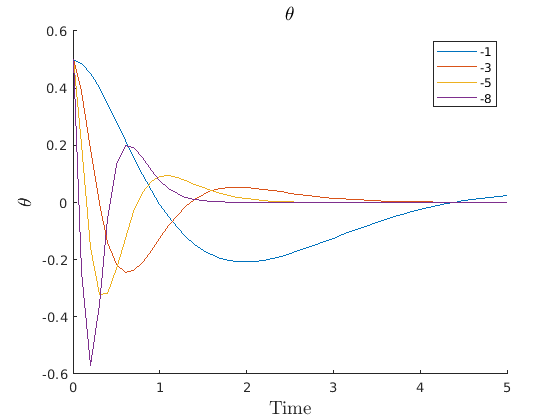

% ---
figure
hold on;

title("$\theta$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("$\theta$", 'Interpreter', 'latex', "FontSize", 14);

for i = 1:length(Ks)
   plot(time, Zdots{i}(:,2)) 
end

legend(string(Ks))

hold off;
exportgraphics(gcf,'theta_plot.png','Resolution',300)

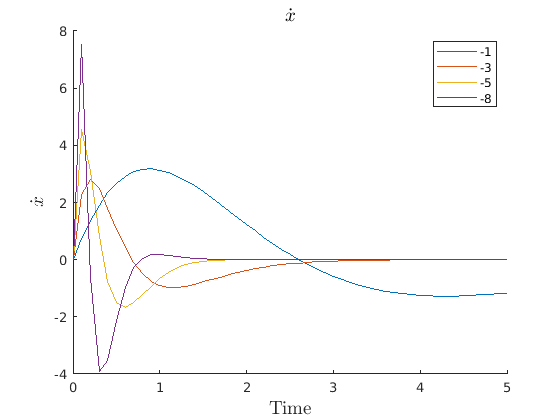

% ---
figure
hold on;

title("$\dot{x}$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("$\dot{x}$", 'Interpreter', 'latex', "FontSize", 14);

for i = 1:length(Ks)
   plot(time, Zdots{i}(:,3)) 
end

legend(string(Ks))

hold off;
exportgraphics(gcf,'xdot_plot.png','Resolution',300)

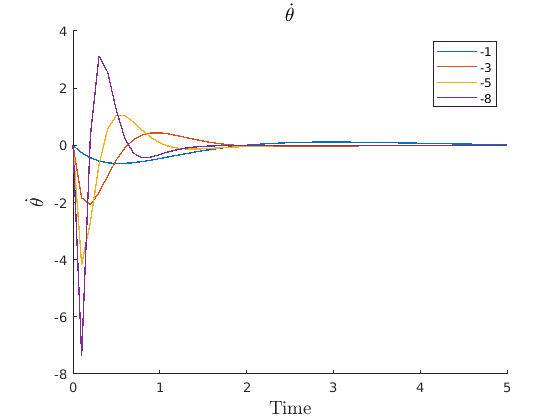

% ---
figure
hold on;

title("$\dot{\theta}$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("$\dot{\theta}$", 'Interpreter', 'latex', "FontSize", 14);

for i = 1:length(Ks)
   plot(time, Zdots{i}(:,4), 'LineWidth', 1) 
end

legend(string(Ks))

hold off;
exportgraphics(gcf,'thetadot_plot.png','Resolution',300)